In this notebook I want to show that sometimes the methods given might numerically fail even though they should "theoretically" converge. Also we will show one of the possible advantages of having more than one method to solve a differential equation. 

What we will do is use the ode45 and ode113 solvers to find solutions of the equation


$$
\begin{cases}
    &\frac{\mathrm{d} x}{\mathrm{~d} t}=\sigma(y-x) \\
    &\frac{\mathrm{d} y}{\mathrm{~d} t}=x(\rho-z)-y \\
    &\frac{\mathrm{d} z}{\mathrm{~d} t}=x y-\beta z
\end{cases}


$$


where $\sigma=10$, $\beta=8/3$ and  $\rho=28$, and  using the initial condition $(x_0,y_0,z_0) = (-8, 8, 27)$.

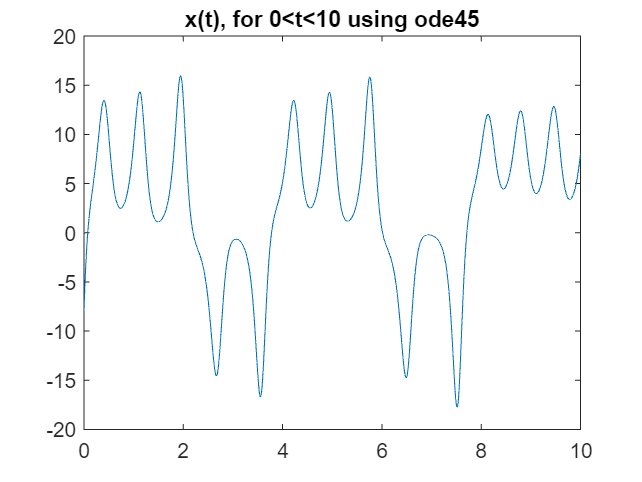

%Set up time interval, initial condition and local truncation error for the
%methods
timeinterval = [0 10];
initcond = [-8,8,27];
odeoptions = odeset('RelTol',10^(-5),'AbsTol',10^(-5));

%Solving the system using ode45
[t1,X1] = ode45(@(t,x) odefun(x),timeinterval,initcond,odeoptions);
%Plotting first component of solution against time
plot(t1,X1(:,1))
title('x(t), for 0<t<10 using ode45')

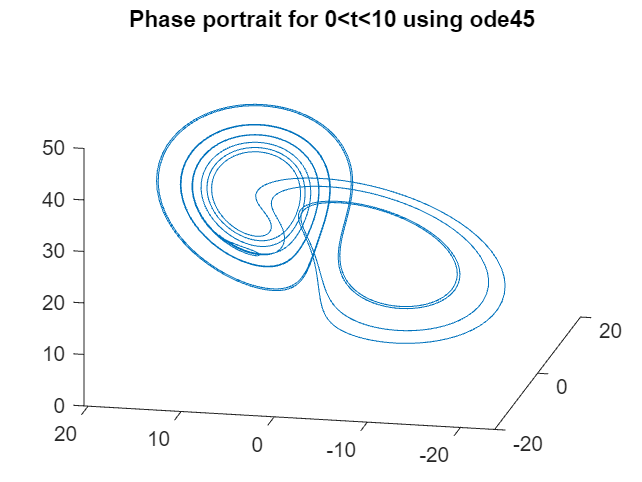

%Plotting phase portrait of the solution in 3 dimensions
plot3(X1(:,1),X1(:,2),X1(:,3))
title('Phase portrait for 0<t<10 using ode45')

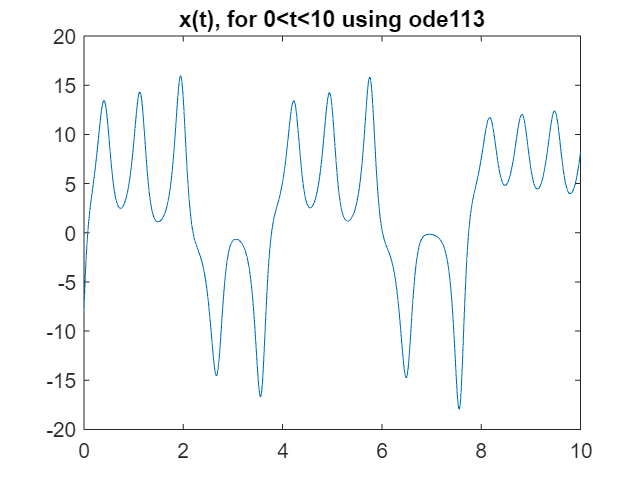

%Solving the system using ode45
[t2,X2] = ode113(@(t,x) odefun(x),timeinterval,initcond,odeoptions);
%Plotting first component of solution against time
plot(t2,X2(:,1))
title('x(t), for 0<t<10 using ode113')

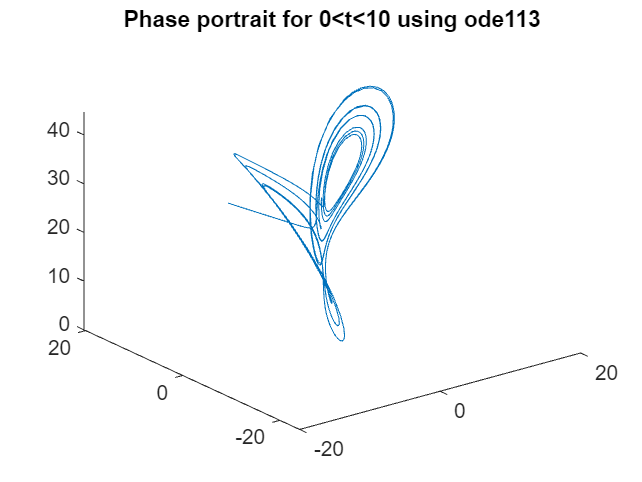

%Plotting phase portrait of the solution in 3 dimensions
plot3(X2(:,1),X2(:,2),X2(:,3))
title('Phase portrait for 0<t<10 using ode113')

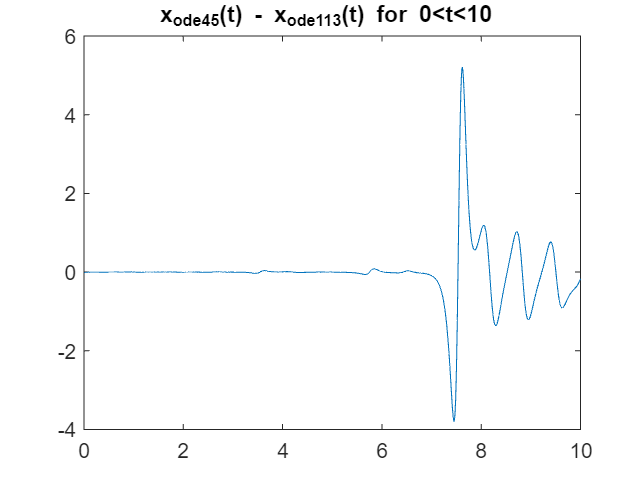

%Plotting the difference in first component of the solution given by both
%methods. Notice that since the discretization points are different we need
%to interpolate in the same set of point to be able to compare. 
plot(t2,interp1(t1,X1(:,1),t2)-interp1(t2,X2(:,1),t2))
title('x_{ode45}(t) - x_{ode113}(t) for 0<t<10 ')

function u = odefun(X)
    sigma = 10;
    beta = 8/3;
    rho = 28;

    u = zeros(3,1);
    u(1) = sigma *(X(2)-X(1));
    u(2) = X(1)*(rho - X(3))-X(2);
    u(3) = X(1)*X(2) - beta*X(3);
end